# Matlab Essentials

Matlab provides a powerful interface for signal processing. In this lecture, we review some essential Matlab skills. 

## **Number Essentials**

Objective: Use MATLAB for numerical calculations

**Format**

We can change the format of numbers in MATLAB as follows:

format short
100/81

ans = 1.2346

format long
100/81

ans =    1.234567901234568


format rat
100/81

ans =      100/81    


format short

**Names and Assignments**

x = 42

x = 42

phi = (1+sqrt(5))/2

phi = 1.6180

Avogadros_constant = 6.0221415e23

Avogadros_constant = 6.0221e+23

camelCaseComplexNumber = -3+4i

camelCaseComplexNumber =   -3.0000 + 4.0000i


**Expressions**

3*4 + 5*6

ans = 42

3 * 4+5 * 6

ans = 42

2*(3 + 4)*3

ans = 42

-2^4 + 10*29/5

ans = 42

3\126

ans = 42

52-8-2

ans = 42

**Iteration**

Use the up-arrow to repeatedly execute a command in the command window

x = sqrt(1+x)

x = 6.5574

x = sqrt(1+x)

x = 2.7491

x = sqrt(1+x)

x = 1.9363

x = sqrt(1+x)

x = 1.7136

## **Basic Programming Constructions**

Objective: Use MATLAB for and while loops and if statements to control execution

**For Loop**

x = 42

x = 42

for k = 1:12
    x = sqrt(1+x);
    disp(x)
end

    6.5574



    2.7491



    1.9363



    1.7136



    1.6473



    1.6270



    1.6208



    1.6189



    1.6183



    1.6181



    1.6181



    1.6180



**While Loop**

x = 42;
k = 1;
while abs(x-sqrt(1+x)) > 5e-5
    x = sqrt(1+x);
    k = k+1;
end
k

k = 12

x

x = 1.6181

**If Statement**

num = round(100*rand(1)) 

num = 42


if mod(num,2) == 1
    disp('Odd') ;
else
    disp('Even') ;
end

Even


## **Matrices and Vectors**

Objective: Use MATLAB to implement matrix and vector calculations. Also plot simple functions.

**Vector and Colon Operator**

k = 1:12

k =      1     2     3     4     5     6     7     8     9    10    11    12


x = (0.0: 0.1: 1.00)'

x =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


**Basic Plotting**

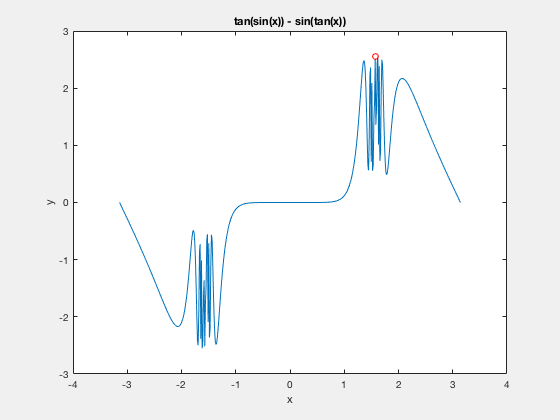

close all
x = -pi: pi/256: pi;
y = tan(sin(x)) - sin(tan(x));
z = 1 + tan(1);
figure ;
set(gcf,'Visible','On')
plot(x,y,'-', pi/2,z,'ro')
xlabel('x')
ylabel('y')
title('tan(sin(x)) - sin(tan(x))')

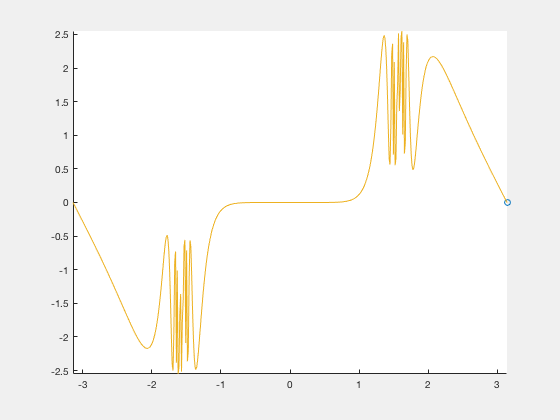


% show a trajectory or comet plot
% need to run this in the command window to see the effect
figure
set(gcf,'Visible','On')
comet(x,y)

## **Matrices**

Use semicolns to separate matrix column elements and commas or space to separate matrix row elements.

x = [2; 4]

x =      2
     4


A = [4 -3; -2 1]

A =      4    -3
    -2     1


y = A*x

y =     -4
     0


B = A'*A

B =     20   -14
   -14    10


C = A*A'

C =     25   -11
   -11     5


A matrices describe linear transformations.

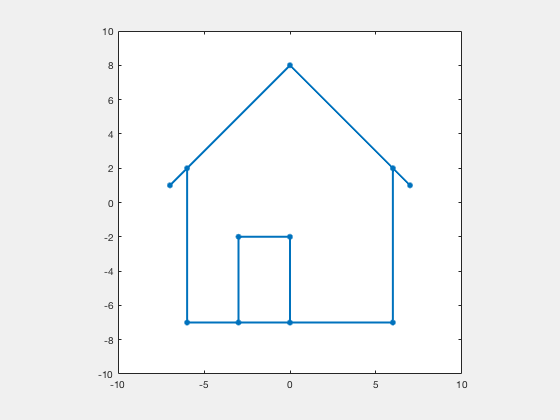

close all ;
dot2dot(house)
set(gcf,'Visible','On')
axis(10*[-1 1 -1 1])

Now apply the transformation

A = [1/2 0 ; 0 1]

A =     0.5000         0
         0    1.0000


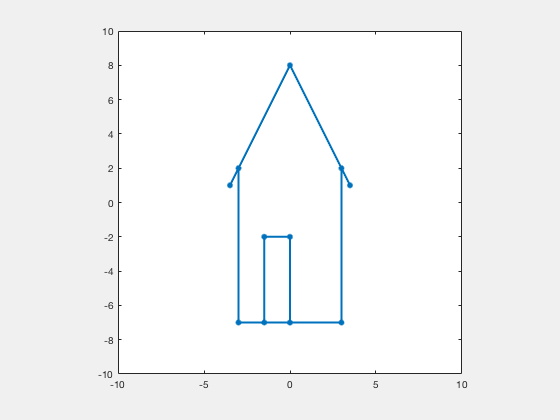

dot2dot(A*house)
axis(10*[-1 1 -1 1]) % sets limits on the plot axis [xmin xman ymin ymax]

A = [1 0; 0 1/2]

A =     1.0000         0
         0    0.5000


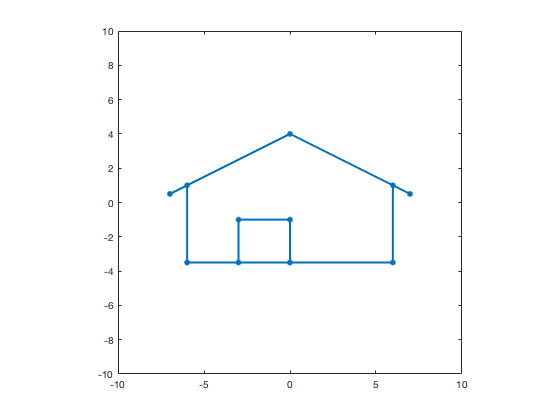

dot2dot(A*house)
axis(10*[-1 1 -1 1])

A = [0 1;1/2 0]

A =              0          1.00
          0.50             0


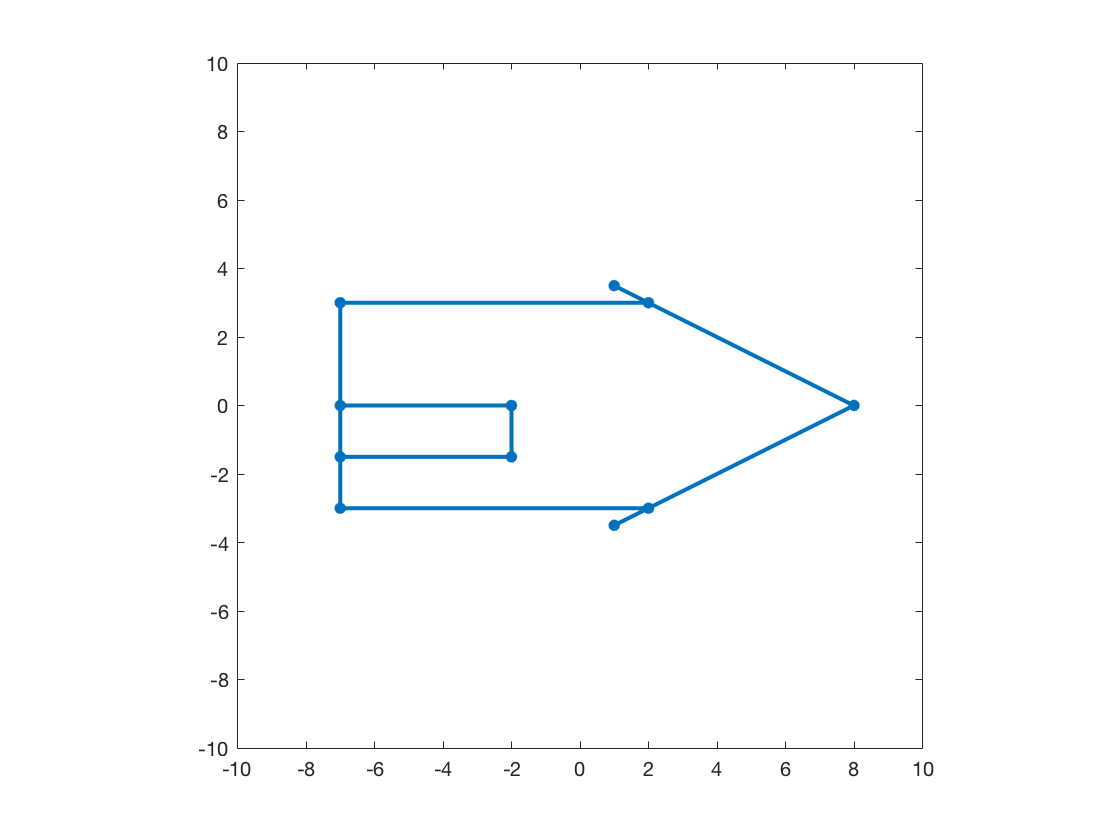

dot2dot(A*house)
axis(10*[-1 1 -1 1])

A = [1/2 0; 0 -1]

A =           0.50             0
             0         -1.00


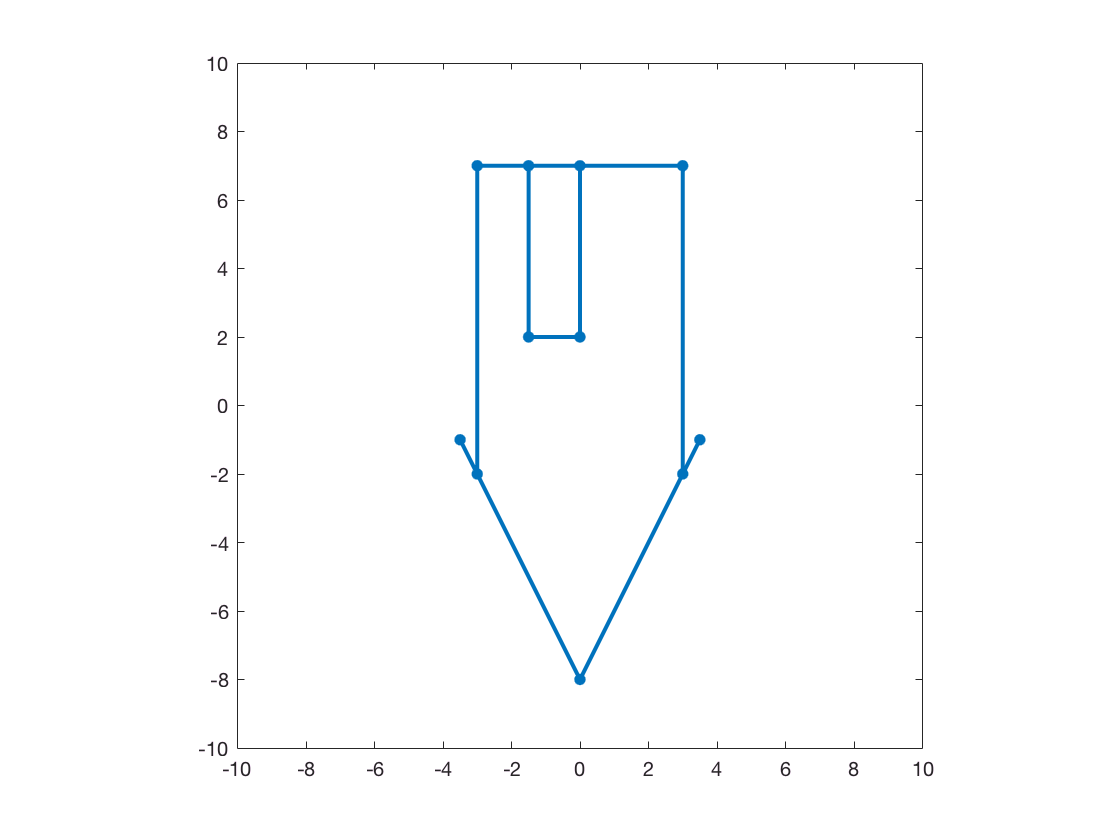

dot2dot(A*house)
axis(10*[-1 1 -1 1])

Create your own linear transformation and see the results

A = [2 3;-1 4]

A =      2     3
    -1     4


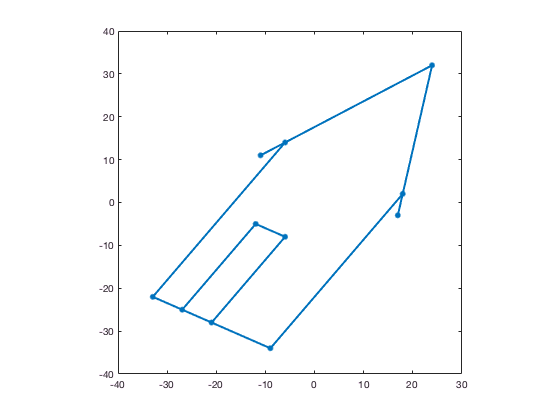

dot2dot(A*house)

Change the matrix A to see what happens.

## Functions in MATLAB

Functions are declated using the function keyword

Here is an example of a function to determine the date of Easter.

-----------------------------------------------------------------------------------

function dn = easter(y)

% EASTER  Date of Easter.

% EASTER(y) is the datenum of Easter in year y.

% Ref: Donald Knuth, The Art of Computer Programming,

%      Fundamental Algorithms, pp. 155-156.

%   Copyright 2014 Cleve Moler

%   Copyright 2014 The MathWorks, Inc.

% Golden number in 19-year Metonic cycle.

g = mod(y,19) + 1;

% Century number.

c = floor(y/100) + 1;

% Corrections for leap years and moon's orbit.

x = floor(3*c/4) - 12;

z = floor((8*c+5)/25) - 5;

% Epact.

e = mod(11*g+20+z-x,30);

if (e==25 && g>11 || e==24), e = e + 1; end

% Full moon.

n = 44 - e;

if n < 21, n = n + 30; end

% Find a Sunday.

d = floor(5*y/4) - x - 10;

% Easter is a Sunday in March or April.

d = n + 7 - mod(d+n,7);

dn = datenum(y,3,d);

disp(['Easter is on ', datestr(dn)])

--------------------------------------------------------------------------------------

num = easter(2025) ;

Easter is on: 20-Apr-2025


## Cool MATLAB Examples

You do not need to understand the code if the following examples, but can play...

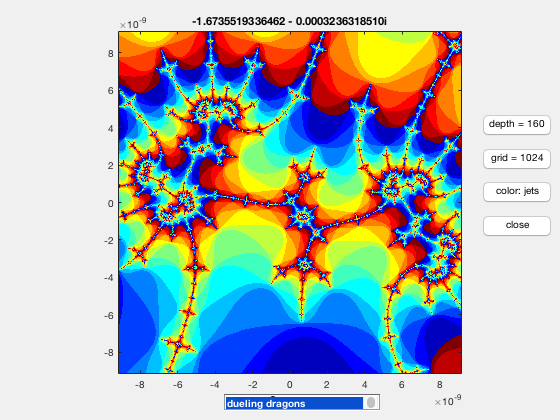

mandelbrot(6)

You can change the number from 1 to 12.

clockex

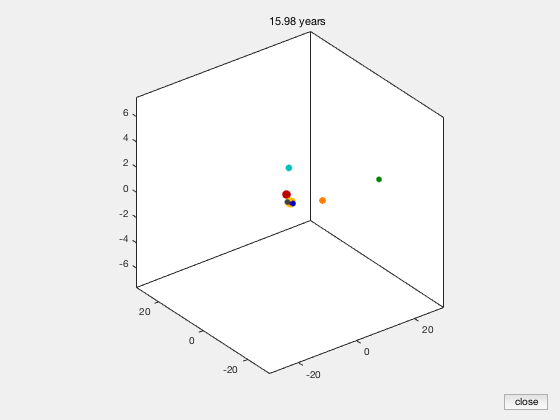

orbits

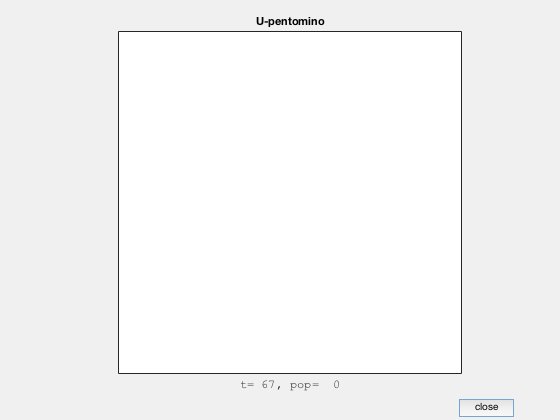

lifex

ans =      3     7     4     1     8     9     6     5     2
     5     2     1     7     3     6     8     9     4
     9     6     8     5     4     2     1     3     7
     2     4     7     6     9     8     3     1     5
     1     9     3     2     7     5     4     8     6
     6     8     5     3     1     4     7     2     9
     7     3     6     9     2     1     5     4     8
     4     5     9     8     6     3     2     7     1
     8     1     2     4     5     7     9     6     3


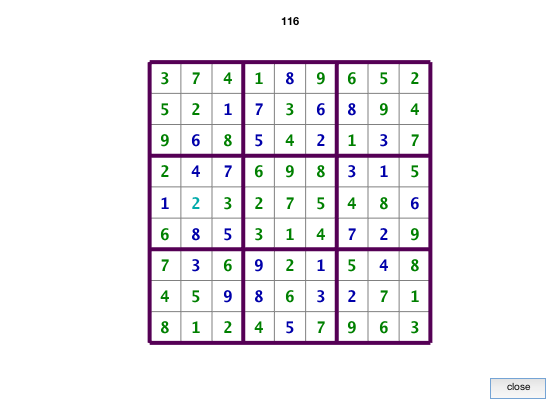

sudoku(sudoku_puzzle(4))

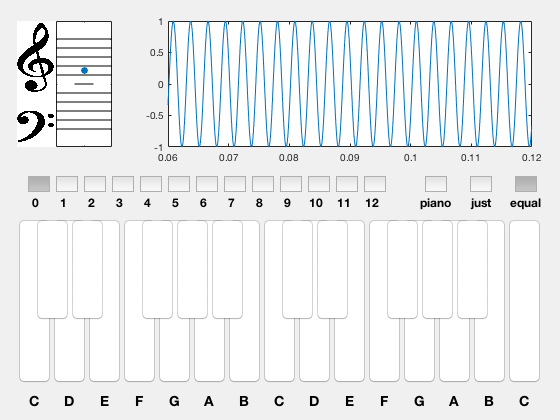

pianoex(5)